# 01 Hands On: Discrete Systems - 2D spring system - Part 1

Transformation of local degree of freedom to global degrees of freedom in 2D:

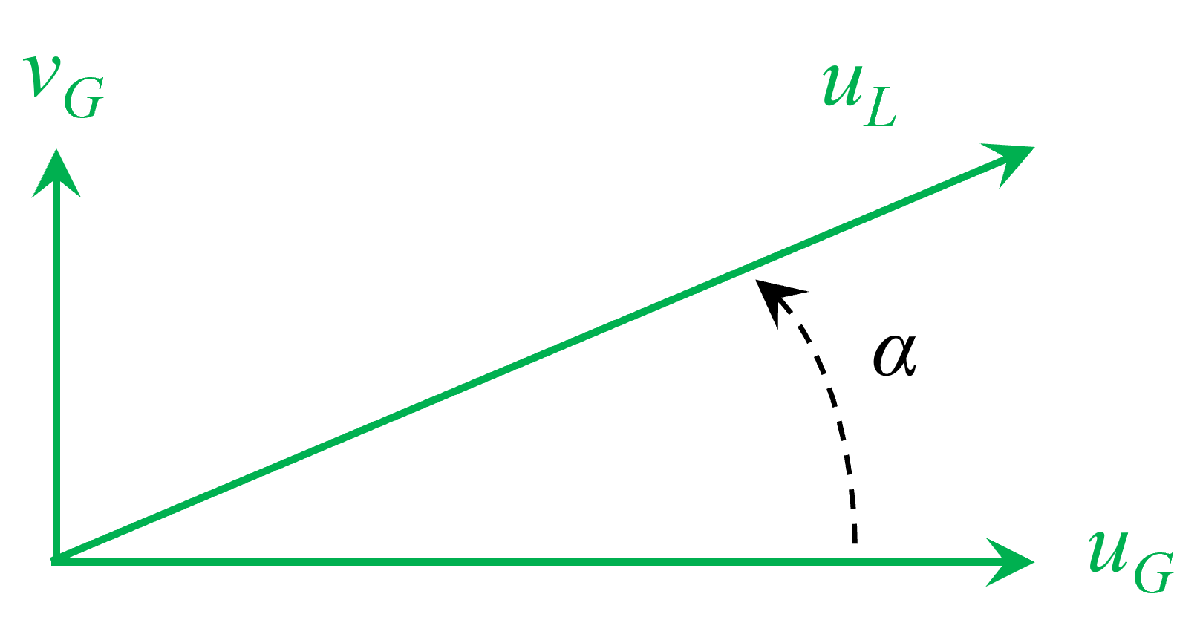


$$u_L =\cos \left(\alpha \right)\;u_G +\sin \left(\alpha \right)\;v_G$$


For 1D element having two degrees of freedom: 

$\left\lbrack \begin{array}{c}
u_{1,L} \\
u_{2,L} 
\end{array}\right\rbrack =\underset{\mathbf{T}}{\underbrace{\left\lbrack \begin{array}{cccc}
\cos \left(\alpha \;\right) & \sin \left(\alpha \right) & 0 & 0\\
0 & 0 & \cos \left(\alpha \right) & \sin \left(\alpha \;\right)
\end{array}\right\rbrack } } \;\left\lbrack \begin{array}{c}
u_{1,G,x} \\
u_{1,G,y} \\
u_{2,G,x} \\
u_{2,G,y} 
\end{array}\right\rbrack$     or    $\left\lbrack \begin{array}{c}
u_{1,G,x} \\
u_{1,G,y} \\
u_{2,G,x} \\
u_{2,G,y} 
\end{array}\right\rbrack =\underset{{\mathbf{T}}^{-1} ={\mathbf{T}}^T }{\underbrace{\left\lbrack \begin{array}{cc}
\cos \left(\alpha \;\right) & 0\\
\sin \left(\alpha \;\right) & 0\\
0 & \cos \left(\alpha \right)\\
0 & \sin \left(\alpha \;\right)
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
u_{1,L} \\
u_{2,L} 
\end{array}\right\rbrack$

clear all; clc; close all;
syms alpha

alpha_e = [-30 45 0]

alpha_e =    -30    45     0


k_e     = [20 15 10]

k_e =     20    15    10



T = [cos(alpha), sin(alpha), 0, 0;
     0, 0, cos(alpha), sin(alpha)]

$$T = \left(\begin{array}{cccc} \cos\left(\alpha \right) & \sin\left(\alpha \right) & 0 & 0\\ 0 & 0 & \cos\left(\alpha \right) & \sin\left(\alpha \right) \end{array}\right)$$

% Stiffness matrix transformation
KEL = [1 -1; -1 1];
subs(T' * KEL * T, alpha, deg2rad(0))

$$ans = \left(\begin{array}{cccc} 1 & 0 & -1 & 0\\ 0 & 0 & 0 & 0\\ -1 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

## Spring system from lecture

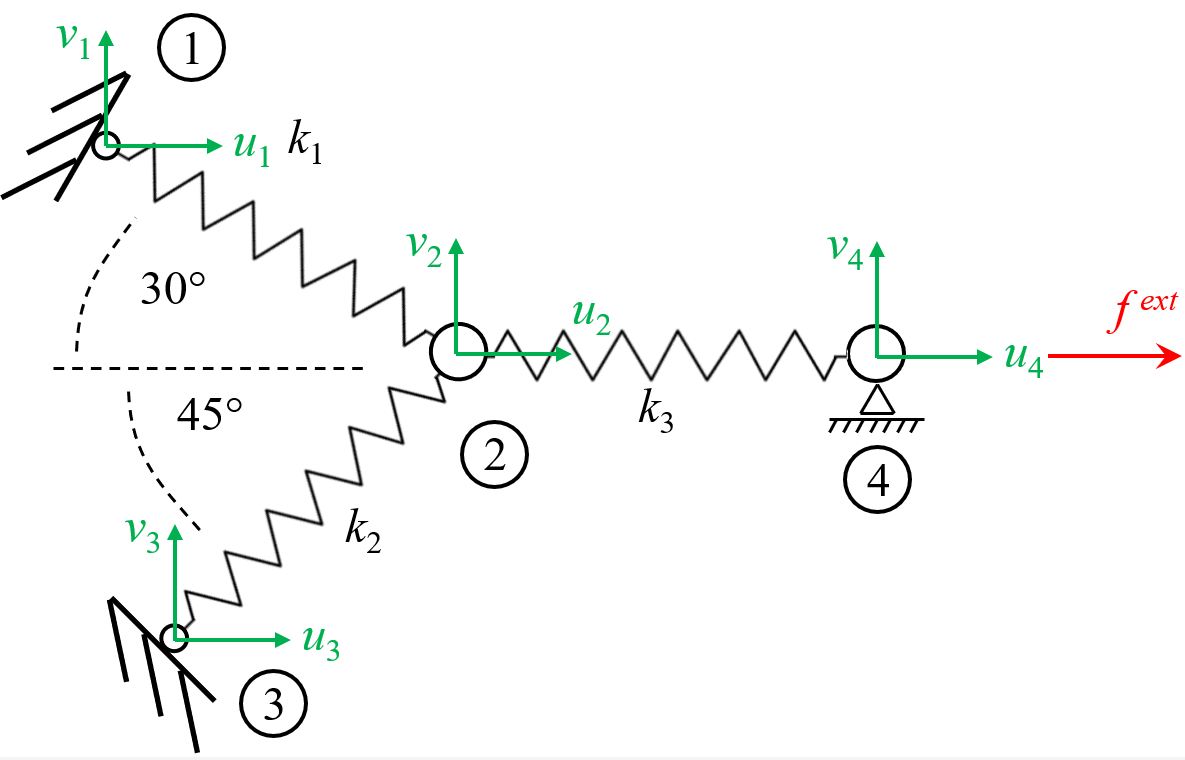

% Set up spring stiffness matrixes and assemble global stiffness matrix
KG = zeros(8);
connectivity = [1 2 3 4; 
                5 6 3 4; 
                3 4 7 8];

% T1 = transformationMatrix(-30); sym(T1);
% K1 = 20 * sym(T1' * KEL * T1);
% KG(connectivity(1,:), connectivity(1,:)) = KG(connectivity(1,:), connectivity(1,:)) + K1;
% 
% T2 = transformationMatrix(45); sym(T2);
% K2 = 15 * T2' * KEL * T2;
% KG(connectivity(2,:), connectivity(2,:)) = KG(connectivity(2,:), connectivity(2,:)) + K2;
% 
% T3 = transformationMatrix(0); sym(T3); 
% K3 = 10 * T3' * KEL * T3;
% KG(connectivity(3,:), connectivity(3,:)) = KG(connectivity(3,:), connectivity(3,:)) + K3;

for element = 1:size(connectivity, 1)
    T_e = transformationMatrix(alpha_e(element)); sym(T_e);
    K_e = k_e(element) * sym(T_e' * KEL * T_e);
    KG(connectivity(element,:), connectivity(element,:)) = KG(connectivity(element,:), connectivity(element,:)) + K_e;
end

KG

KG =    15.0000   -8.6603  -15.0000    8.6603         0         0         0         0
   -8.6603    5.0000    8.6603   -5.0000         0         0         0         0
  -15.0000    8.6603   32.5000   -1.1603   -7.5000   -7.5000  -10.0000         0
    8.6603   -5.0000   -1.1603   12.5000   -7.5000   -7.5000         0         0
         0         0   -7.5000   -7.5000    7.5000    7.5000         0         0
         0         0   -7.5000   -7.5000    7.5000    7.5000         0         0
         0         0  -10.0000         0         0         0   10.0000         0
         0         0         0         0         0         0         0         0


% Force vector and solution
u = zeros(8, 1);

The force vector must have the same size as the vector of degrees of freedom eventually. To initialize the complete vector to 0 could be misleading, so we only define the known external loads and leave the computation of reaction forces for the postprocessing.

fixeddof = [1, 2, 5, 6, 8];         
freedof = setdiff(1 : 8, fixeddof)

freedof =      3     4     7


% f = [0; 0; 10];
% u(freedof) = KG(freedof, freedof) \ f

f = [0; 0; 0; 0; 0; 0; 10; 0];
u(freedof) = KG(freedof, freedof) \ f(freedof)

u =          0
         0
    0.4466
    0.0415
         0
         0
    1.4466
         0


### Visualization

x0 = zeros(4,2);

x0(3, :) = [0, 
            0];
x0(2, :) = [cosd(45), 
            cosd(45)];
x0(1, :) = [x0(2, 1) - cosd(-30), 
            x0(2, 2) - sind(-30)];
x0(4, :) = [x0(2, 1) + 1, 
            x0(2, 2)];

plotSpringSystem(x0, connectivity);

The displacement vector can not be added directly to the nodal coordinates. We have to reshape the vector so the displacements match the corresponding degrees of freedom.

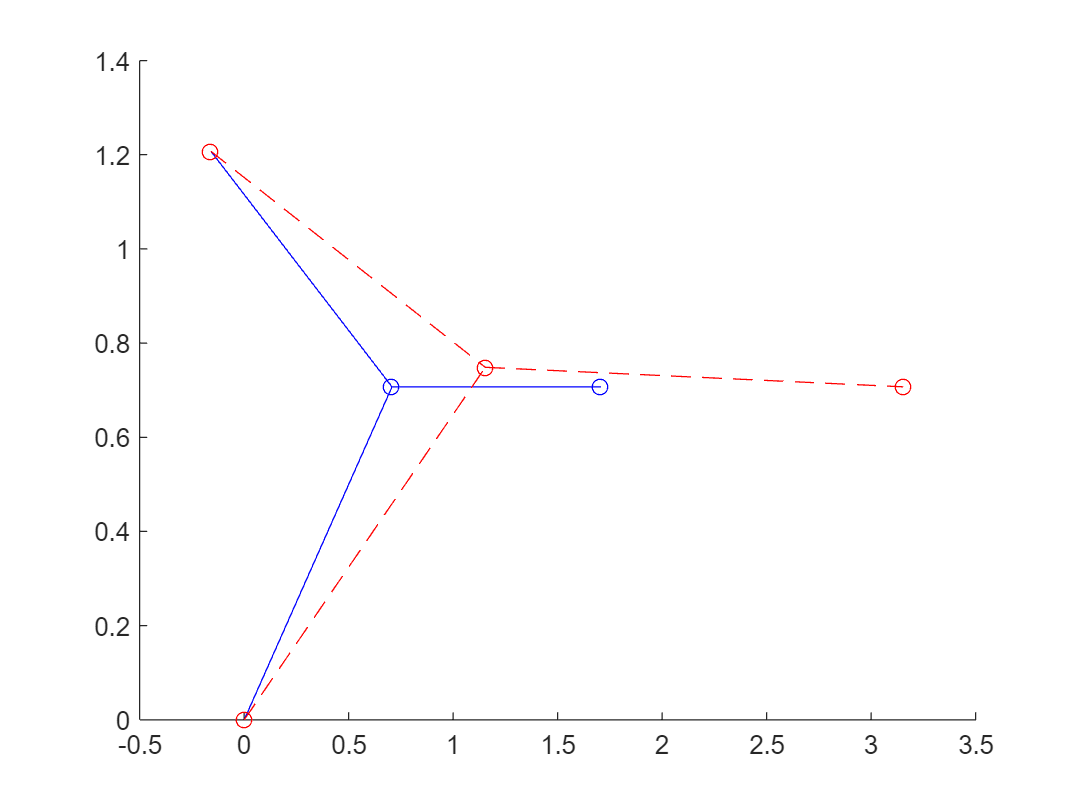

plotSpringSystem(x0 + transpose(reshape(u, 2, 4)), connectivity, 'red')

Following the derivation of the transformation, we can compute the local deformation of a spring using


$$\left\lbrack \begin{array}{c}
u_{1,L} \\
u_{2,L} 
\end{array}\right\rbrack =\underset{\mathbf{T}}{\underbrace{\left\lbrack \begin{array}{cccc}
\cos \left(\alpha \;\right) & \sin \left(\alpha \right) & 0 & 0\\
0 & 0 & \cos \left(\alpha \right) & \sin \left(\alpha \;\right)
\end{array}\right\rbrack } } \;\left\lbrack \begin{array}{c}
u_{1,G,x} \\
u_{1,G,y} \\
u_{2,G,x} \\
u_{2,G,y} 
\end{array}\right\rbrack$$


% Deformation of springs in local coordinate system
u1 = transformationMatrix(-30) * u(connectivity(1,:));
u2 = transformationMatrix(45) * u(connectivity(2,:));
u3 = transformationMatrix(0) * u(connectivity(3,:))

u3 =     0.4466
    1.4466


function plotSpringSystem(x, connectivity, color)
    % Plot lines between two points of the given nodal positions using given connectivity
    % INPUT
    %   x (array)               Nodal coordinates in format [x1, y1; x2 y2; ...] 
    %   connectivity (array)    Array of nodes per spring
    %   color (string/array)    OPTIONAL Color for spring in plot
    if nargin < 3
        color = 'blue';        % Default color: blue
        lineStyle = '-o';   % Default linestyle
    else
        lineStyle = '--o';
    end
    % Reshape nodes in order to be able to use the DOF indicies from the connectivity
    % matrix to extract the correct nodal coordinates via linear indexing.
    nodes = x';

    hold on;
    for spring = 1 : size(connectivity, 1)
        springConnectivity = connectivity(spring, :);
        plot(nodes(springConnectivity([1, 3])), nodes(springConnectivity([2, 4])), lineStyle, Color = color)
    end
    hold off;
end

function T = transformationMatrix(angle)
    % Returns transformation matrix for two local degrees of freedom to global 2D system
    % INPUT
    %   angle (float)   Rotation angle in degrees
    T = [cosd(angle), sind(angle), 0, 0;
        0, 0, cosd(angle), sind(angle)];
end